# Activity 5

# OFDM Modulation with the Inverse FFT - MULTIPATH

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up a 16-QAM link with OFDM modulation.

numBits = 32768;  % power of 2, to optimize performance of fft/ifft
modOrder = 16;  % for 16-QAM

srcBits = randi([0,1],numBits,1);
qamModOut = qammod(srcBits,modOrder,"InputType","bit","UnitAveragePower",true);
ofdmModOut = ifft(qamModOut);

hasMultipath = true;
hasAWGN = false;

SNR = 15;

chanOut = channel(ofdmModOut,hasMultipath,hasAWGN,SNR); 

Demodulate the received signal and calculate the BER.

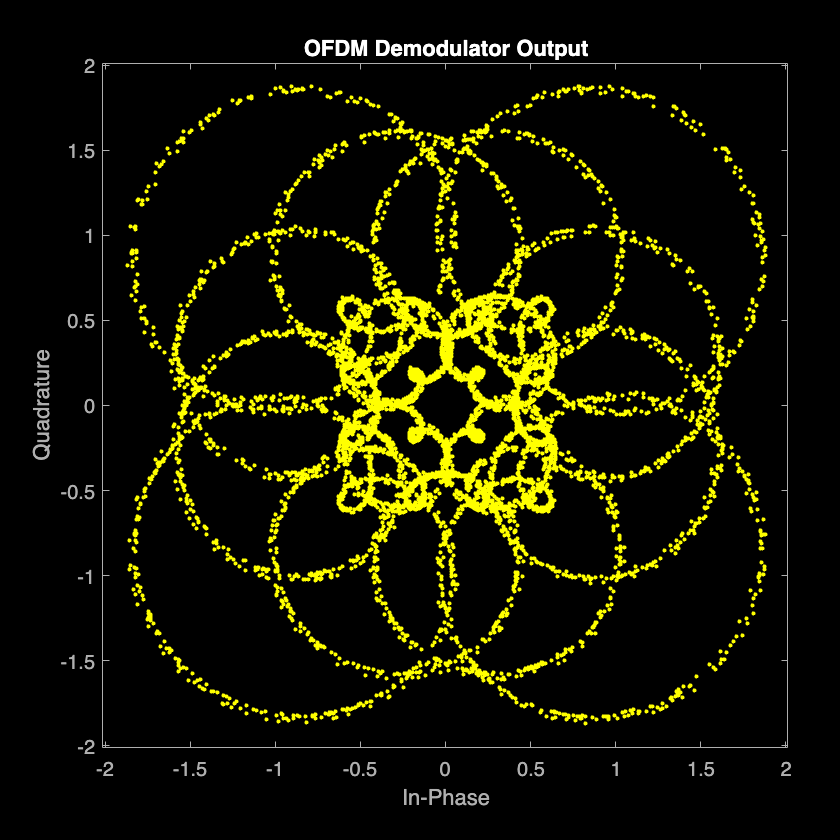

ofdmDemodOut = fft(chanOut);
scatterplot(ofdmDemodOut)
title("OFDM Demodulator Output")


qamDemodOut = qamdemod(ofdmDemodOut,modOrder,"OutputType","bit","UnitAveragePower",true);
numBitErrors = nnz(srcBits~=qamDemodOut)

numBitErrors = 7462

BER = numBitErrors/numBits

BER = 0.2277

FURTHER PRACTICE

The multipath has again rendered the link useless. You can isolate the multipath channel's impact by clearing the `hasAWGN` check box.

You can see the frequency-selective nature of a multipath channel in the scatter plot. A complex gain scales and rotates the constellation, and different frequencies are subject to different complex gains.

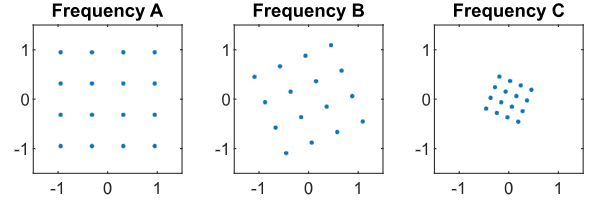

It turns out that the IFFT alone doesn't address all the challenges introduced by a multipath channel. To create a usable link, you'll need to design a more practical OFDM system.

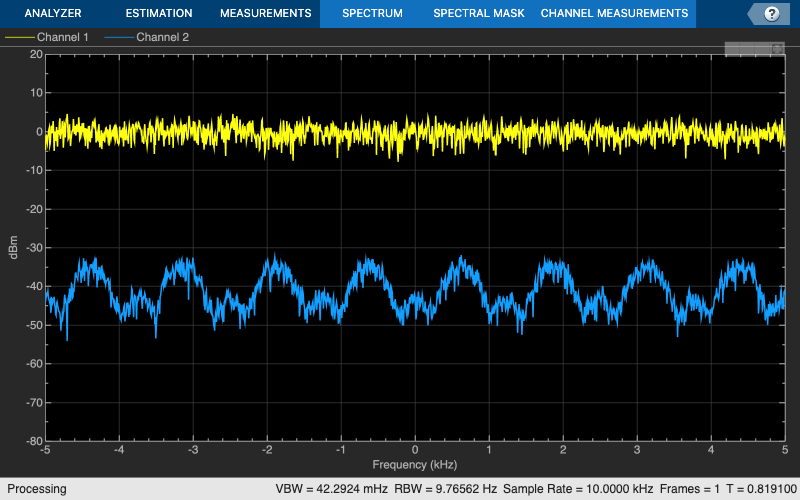

specAn = dsp.SpectrumAnalyzer("NumInputPorts",2,"SpectralAverages", ...
    50,"ShowLegend",true);
specAn(qamModOut,chanOut)